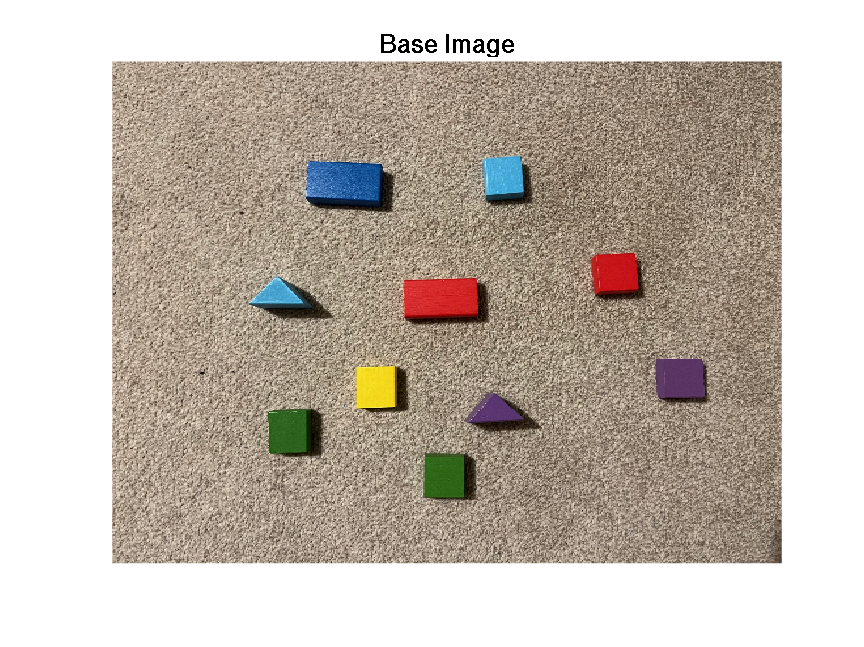


% This is the second attempt at this question,
% due to the realization that the background is
% less saturated than foreground which HSV encodes
clear all;
close all;
raw = imread("Images/easy.jpg");
raw_med = imread("Images/medium.jpg");
raw_hard = imread("Images/hard.jpg");
raw_vh = imread("Images/very_hard.jpg");
raw_extreme = imread("Images/extreme.jpg");

imshow(raw); title("Base Image");

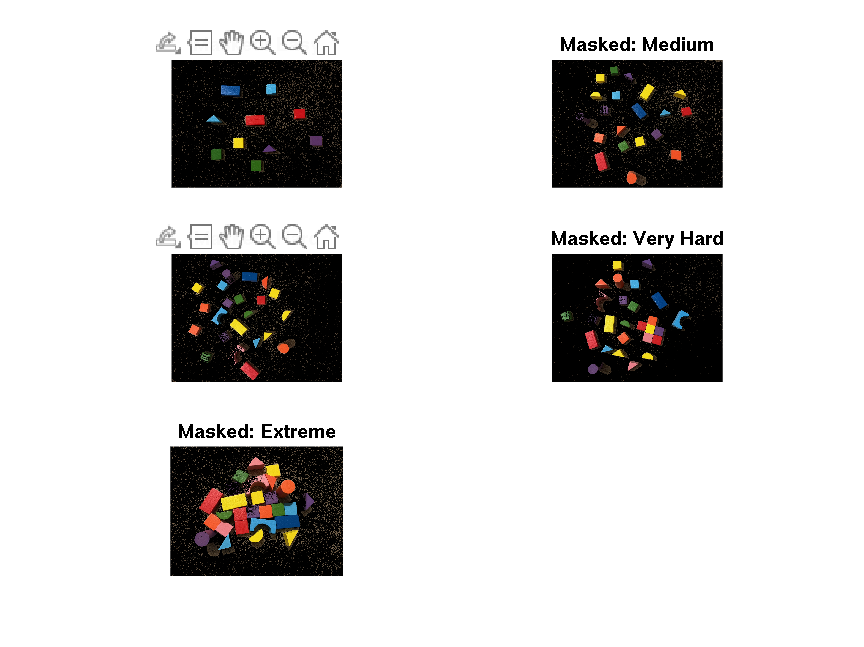


rawHSV = rgb2hsv(raw);
hsvMed = rgb2hsv(raw_med);
hsvHard = rgb2hsv(raw_hard);
hsvVH = rgb2hsv(raw_vh);
hsvEx = rgb2hsv(raw_extreme);

Srange = [0.000 0.31];

mask = (rawHSV(:,:,2) >= Srange(1)) & (rawHSV(:,:,2) <= Srange(2));
mask_m = (hsvMed(:,:,2) >= Srange(1)) & (hsvMed(:,:,2) <= Srange(2));
mask_h = (hsvHard(:,:,2) >= Srange(1)) & (hsvHard(:,:,2) <= Srange(2));
mask_vh = (hsvVH(:,:,2) >= Srange(1)) & (hsvVH(:,:,2) <= Srange(2));
mask_ex = (hsvEx(:,:,2) >= Srange(1)) & (hsvEx(:,:,2) <= Srange(2));

% Set background of all HSV channels to 0
masked = rawHSV;
masked(repmat(mask,[1 1 3])) = 0;

maskedMed = hsvMed;
maskedHard = hsvHard;
maskedVH = hsvVH;
maskedEx = hsvEx;

maskedMed(repmat(mask_m,[1 1 3])) = 0;
maskedHard(repmat(mask_h,[1 1 3])) = 0;
maskedVH(repmat(mask_vh,[1 1 3])) = 0;
maskedEx(repmat(mask_ex,[1 1 3])) = 0;

masked = im2uint8(hsv2rgb(masked));
maskedMed = im2uint8(hsv2rgb(maskedMed));
maskedHard = im2uint8(hsv2rgb(maskedHard));
maskedVH = im2uint8(hsv2rgb(maskedVH));
maskedEx = im2uint8(hsv2rgb(maskedEx));

subplot(3,2,1); imshow(masked); title("Masked: Easy");
subplot(3,2,2); imshow(maskedMed); title("Masked: Medium");
subplot(3,2,3); imshow(maskedHard); title("Masked: Hard");
subplot(3,2,4); imshow(maskedVH); title("Masked: Very Hard");
subplot(3,2,5); imshow(maskedEx); title("Masked: Extreme");

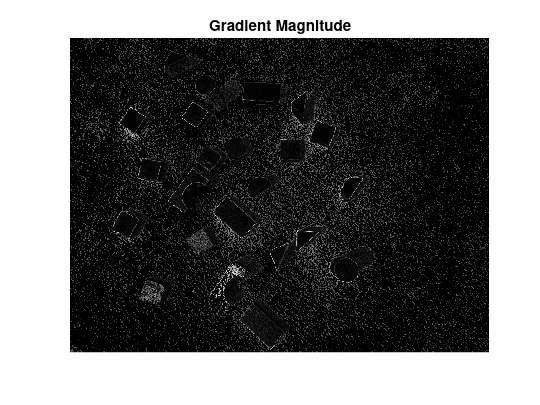

I = im2gray(masked);

gmag = imgradient(I);
imshow(gmag,[])
title("Gradient Magnitude")

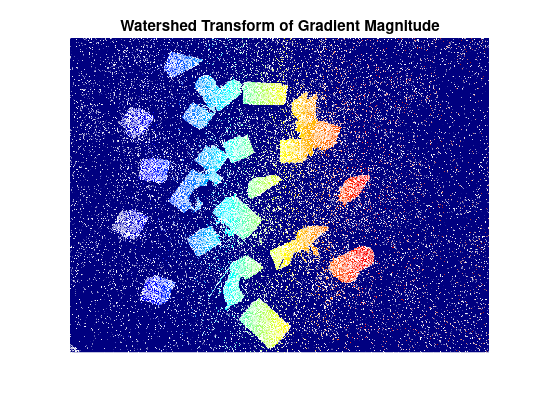

L = watershed(gmag);
Lrgb = label2rgb(L);
imshow(Lrgb)
title("Watershed Transform of Gradient Magnitude")

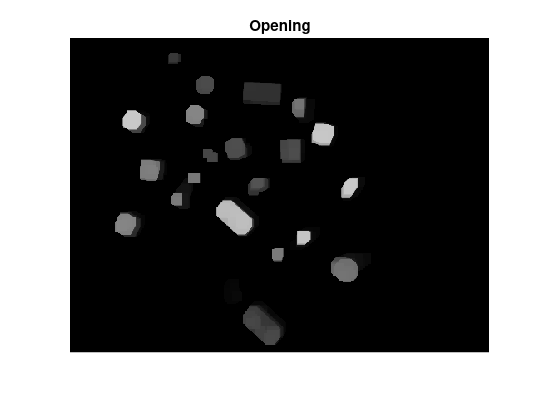

se = strel("square",40);
Io = imopen(I,se);
imshow(Io)
title("Opening")

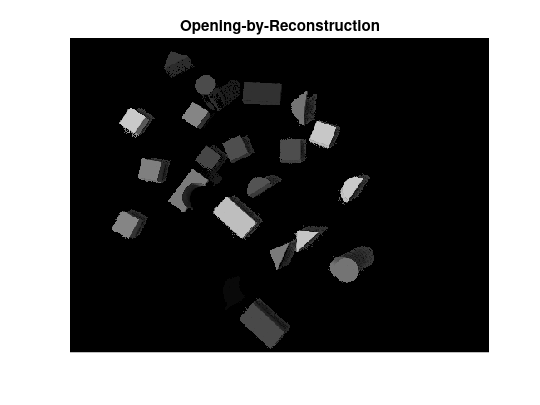


Ie = imerode(I,se);
Iobr = imreconstruct(Ie,I);
imshow(Iobr)
title("Opening-by-Reconstruction")

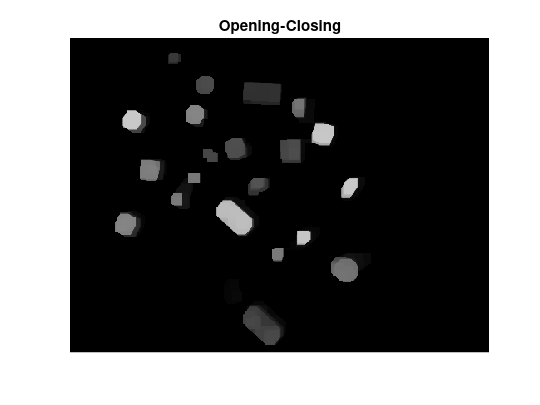


Ioc = imclose(Io,se);
imshow(Ioc)
title("Opening-Closing")

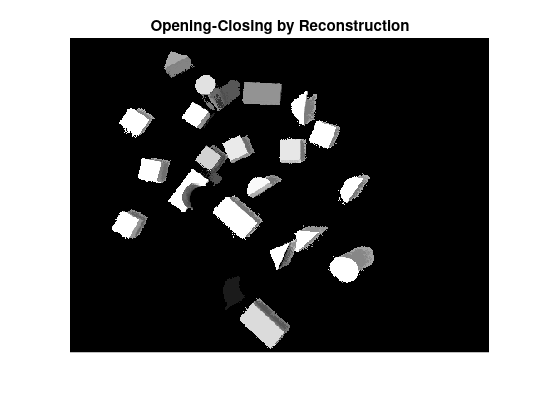


Iobrd = imdilate(Iobr,se);
Iobrcbr = imreconstruct(imcomplement(Iobrd),imcomplement(Iobr));
Iobrcbr = imcomplement(Iobrcbr).*3;
imshow(Iobrcbr)
title("Opening-Closing by Reconstruction")

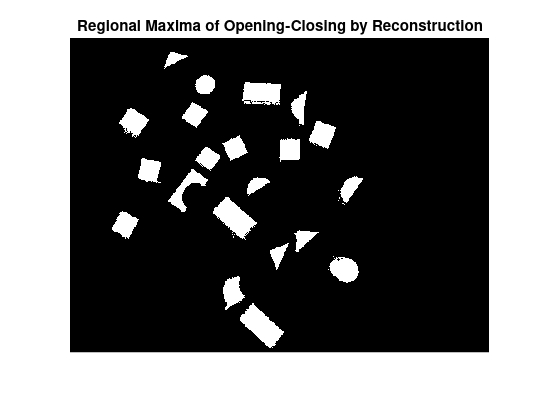

fgm = imregionalmax(Iobrcbr);
imshow(fgm)
title("Regional Maxima of Opening-Closing by Reconstruction")

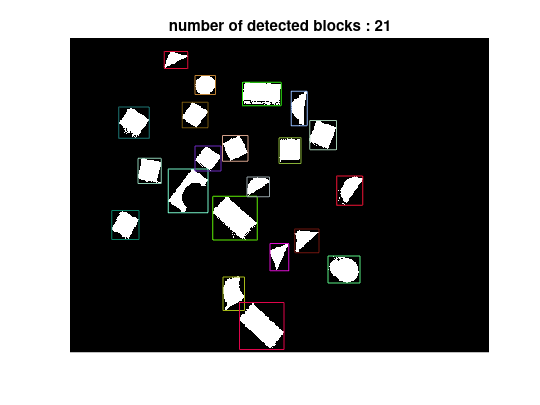

fgm_img = imbinarize(mat2gray(fgm));

stat = regionprops(fgm_img,'BoundingBox');
str = sprintf('number of detected blocks : %d', length(stat));
imshow(fgm_img); title(str); hold on;
for cnt = 1 : length(stat)
    bb = stat(cnt).BoundingBox;
    rectangle('position',bb,'edgecolor',rand(1,3));    
end